# Simulate rolling shutter effects

Simulate the effects of a rolling shutter, the most common type of shutter in a CMOS imager.

See also: sceneRotate, sensorCompute, ipCompute

Copyright Imageval, LLC, 2014

ieInit;
ieSessionSet('wait bar','off');

## Set the parameters needed to make a rotating series of star patterns

iSize  = 128;
nLines = 4;
fov    = 3;
scene  = sceneCreate('star pattern',iSize,'ee',nLines);
scene  = sceneSet(scene,'fov',fov);
oi     = oiCreate;

% Create a sensor whose field of view matches the scene size
sensor    = sensorCreate;
pixelSize = [1.4 1.4]*1e-6;    % Pixel size of 1.4 um
sensor    = sensorSet(sensor,'pixel size constant fill factor',pixelSize);
sensor    = sensorSet(sensor,'fov',sceneGet(scene,'fov')/2,oi);
sz        = sensorGet(sensor,'size');

% Exposure time of the complete image (all rows).  As we increase the
% exposure time, the rotating line turns into a wedge.  The width of the
% wedge increases with exposure time.
expTime = 1e-4;    % Millisecond regime
sensor  = sensorSet(sensor,'exp time',expTime);

% Read out time per row (should be microsecond range).
%
% The delay between reading the first and last row is
%
%    perRow * (number of rows)
%
% At the end of this routine, we assemble the final image by assuming that
% the reset time is delayed in the same way that the read out time is
% delayed.  This gives every row the same exposure duration, but the
% acquisition period of each of the rows is delayed in time.
% To see a bigger effect of the rolling shutter, make this number bigger.
perRow  = 10e-6;

% How many total captures do we need? Number of rows plus enough additional
% captures for last row
nFrames = sz(1) + round(expTime/perRow);

% Store the sensor volts from each capture separately, before we assemble.
v  = zeros(sz(1),sz(2),nFrames);

% The number of degrees the rays rotate between each row capture (perRow).
% The deg per second is rate/perRow or in total rotations per second
% rate/perRow/360.  The faster the rotation, the more the curvature.
rate = 0.3;

fprintf('Computing %i frames\nRotation rate: %.2f (cycles per sec)\n',nFrames,rate/perRow/360);

Computing 70 frames
Rotation rate: 83.33 (cycles per sec)


## This is the scene we will rotate

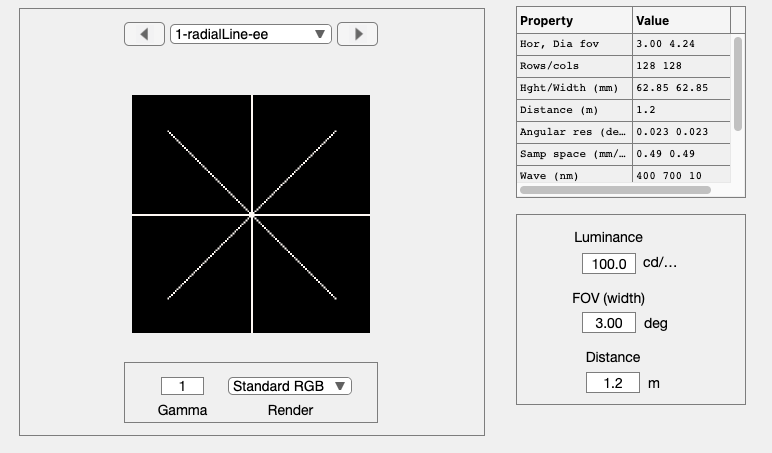

sceneWindow(scene);

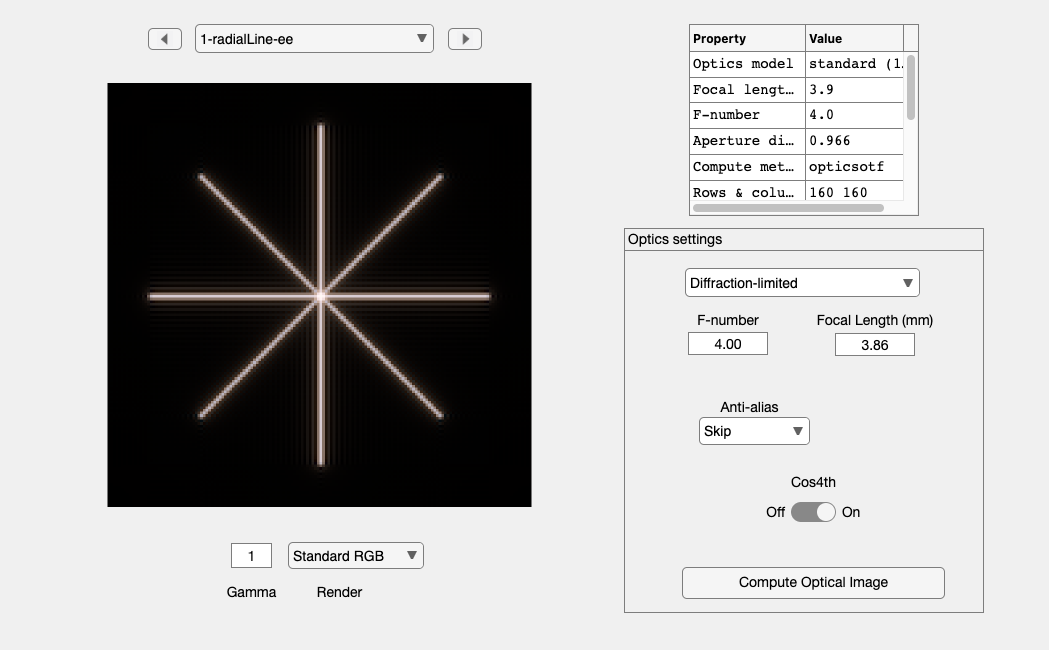


oi = oiCompute(oi,scene);
oiWindow(oi);

## Make the pattern with sceneRotate, then acquire with sensorCompute

w = waitbar(0,'Rotating scenes');
S = 160;   % This is the size of the cropped oi
for ii=1:nFrames
    waitbar(ii/nFrames,w,sprintf('Scene %i',ii));
    
    % Rotation shrink the image at the boundary by adding in zero values
    % where there is an unknown extrapolation.  We remove this by the
    % cropping below.
    deg = ii*rate;
    s = sceneRotate(scene,deg);
    % ieAddObject(s); sceneWindow;
    
    % Compute and crop to keep just the center
    oi = oiCompute(oi,s);
    cp = oiGet(oi,'center pixel');
    rect = round([cp(1) - S/2,  cp(2) - S/2,   S,   S]);
    oiC = oiCrop(oi,rect);
    % ieAddObject(oiC); oiWindow;
    
    sensor = sensorCompute(sensor,oiC);
    if ii==1
        % After first capture, set noise to photon only
        sensor = sensorSet(sensor,'noise flag',1);
    end
    
    v(:,:,ii) = sensorGet(sensor,'volts');
end
close(w)

## These are the individual sensor frames

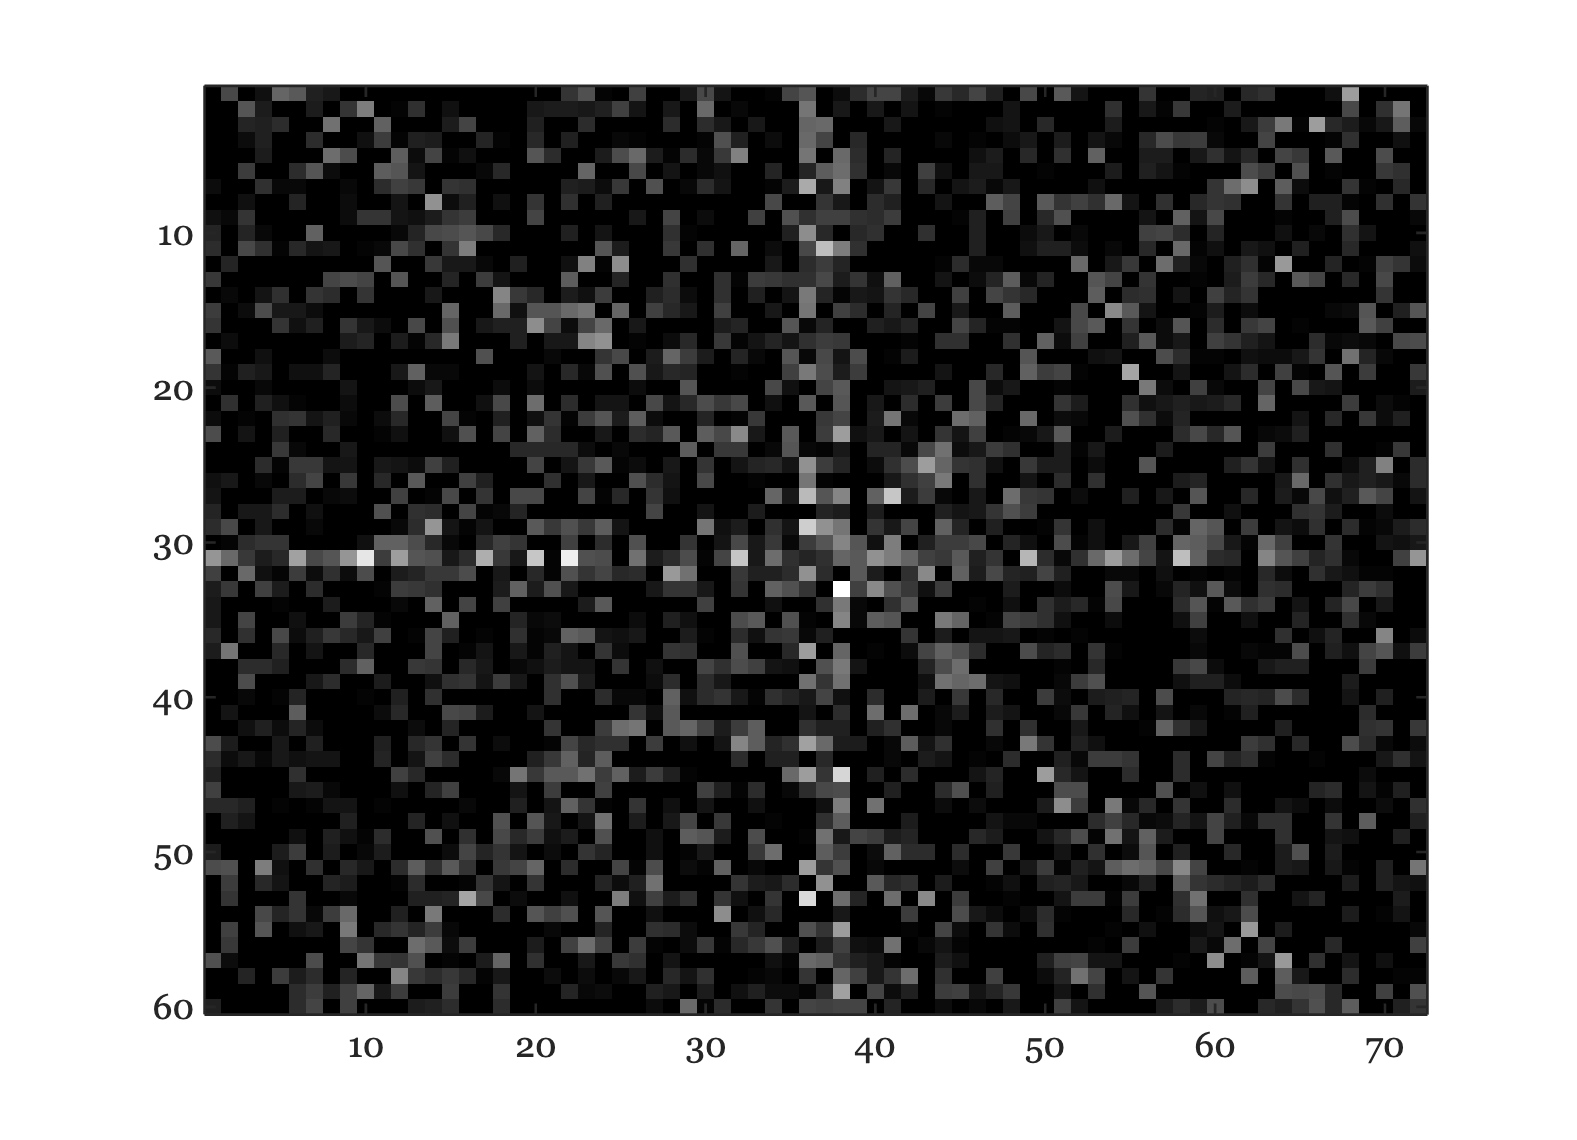

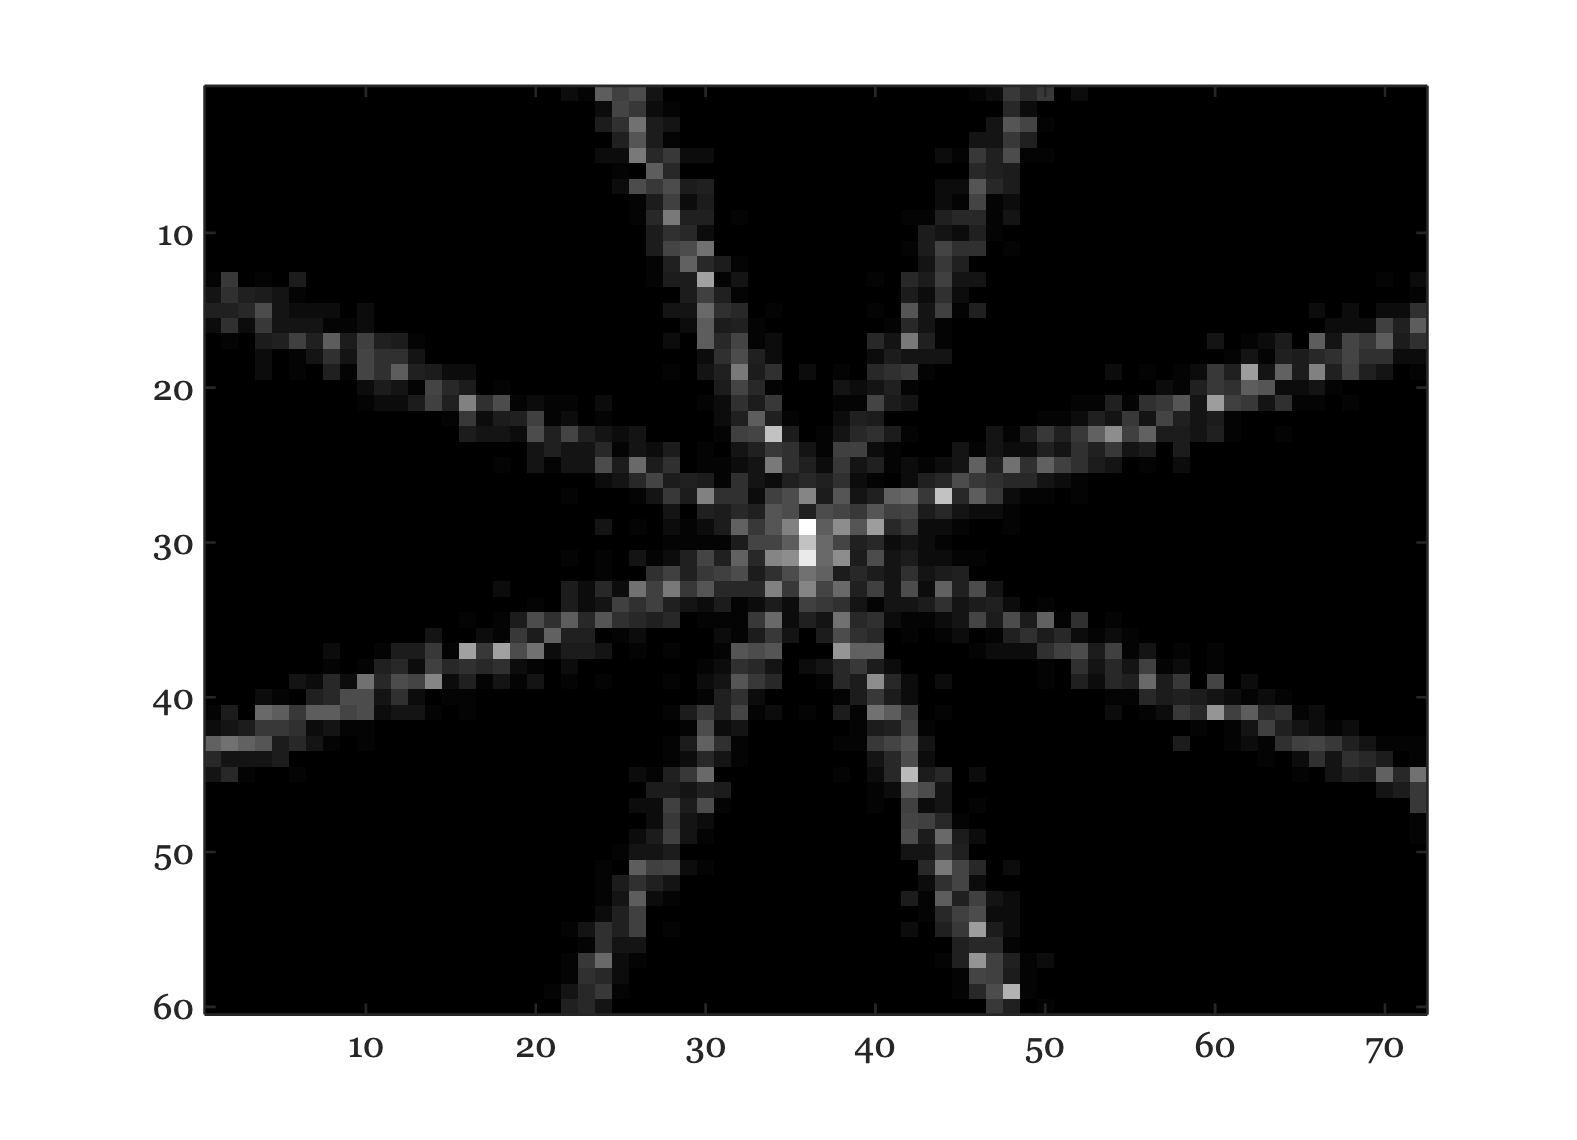

ieFigure; colormap(gray(64)); axis image; axis off
fps = 7;
for ii=1:nFrames
    imagesc(v(:,:,ii)); pause(1/fps);
end

## Create the final sensor image by summing appropriate sensor images

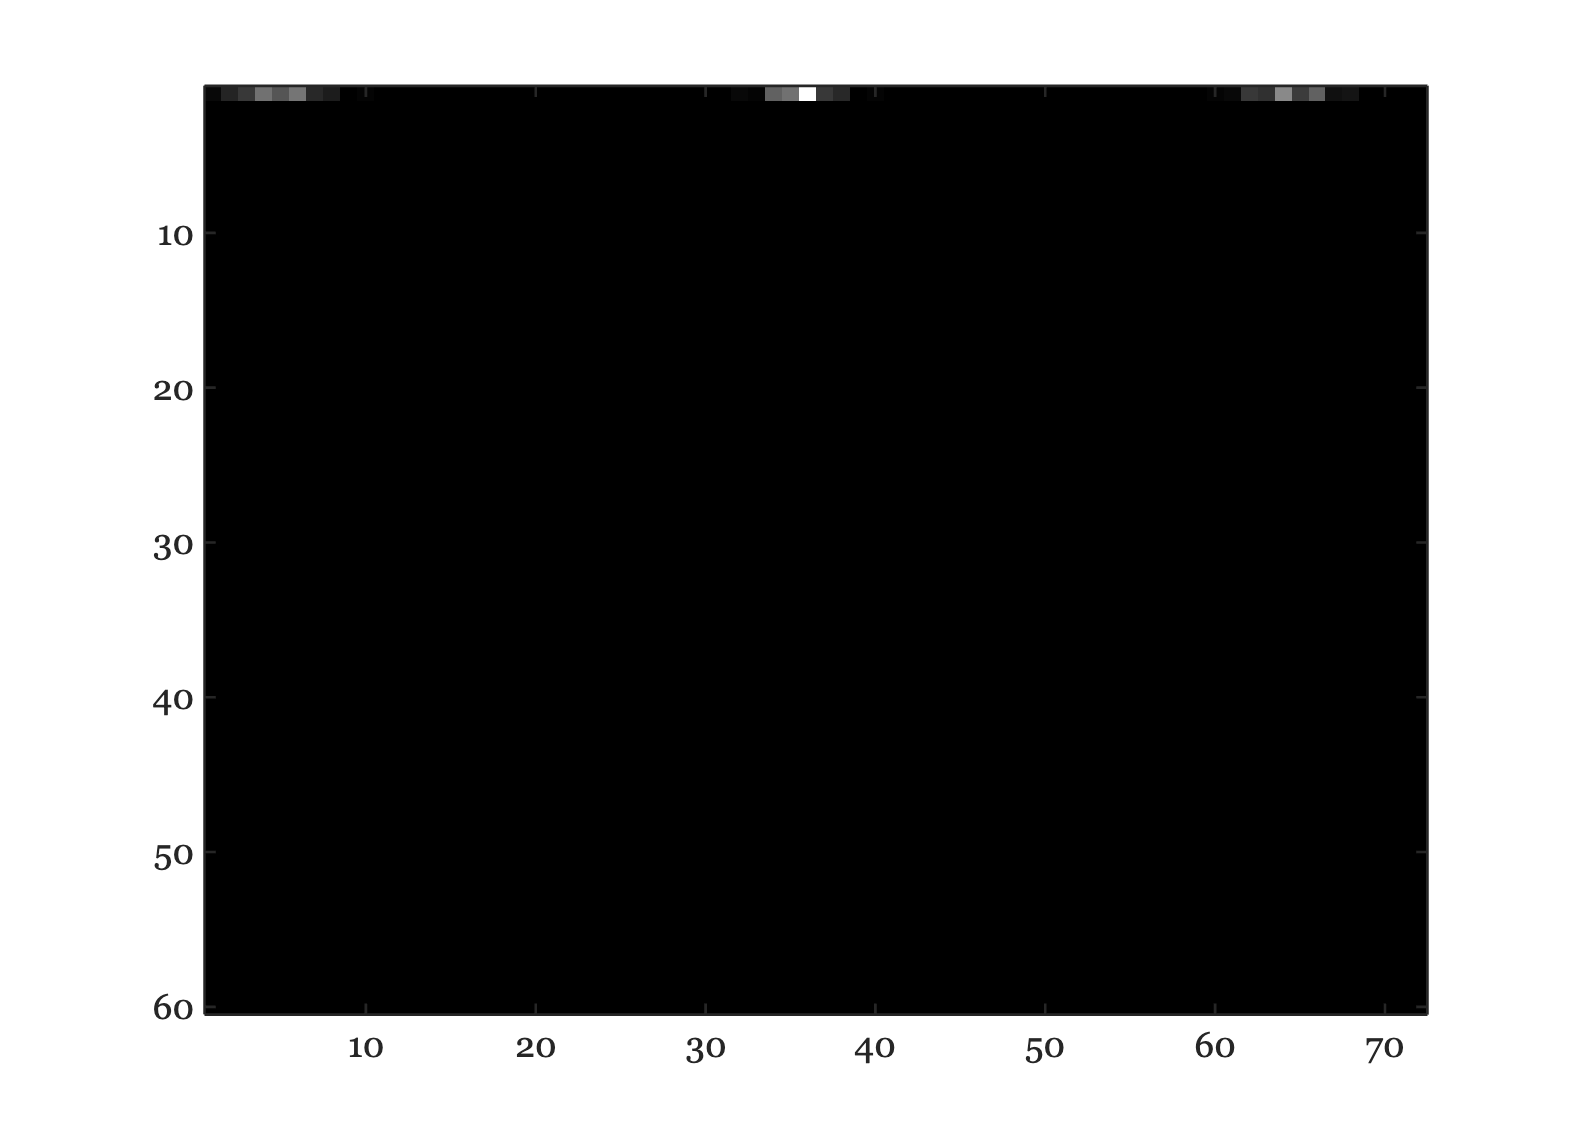

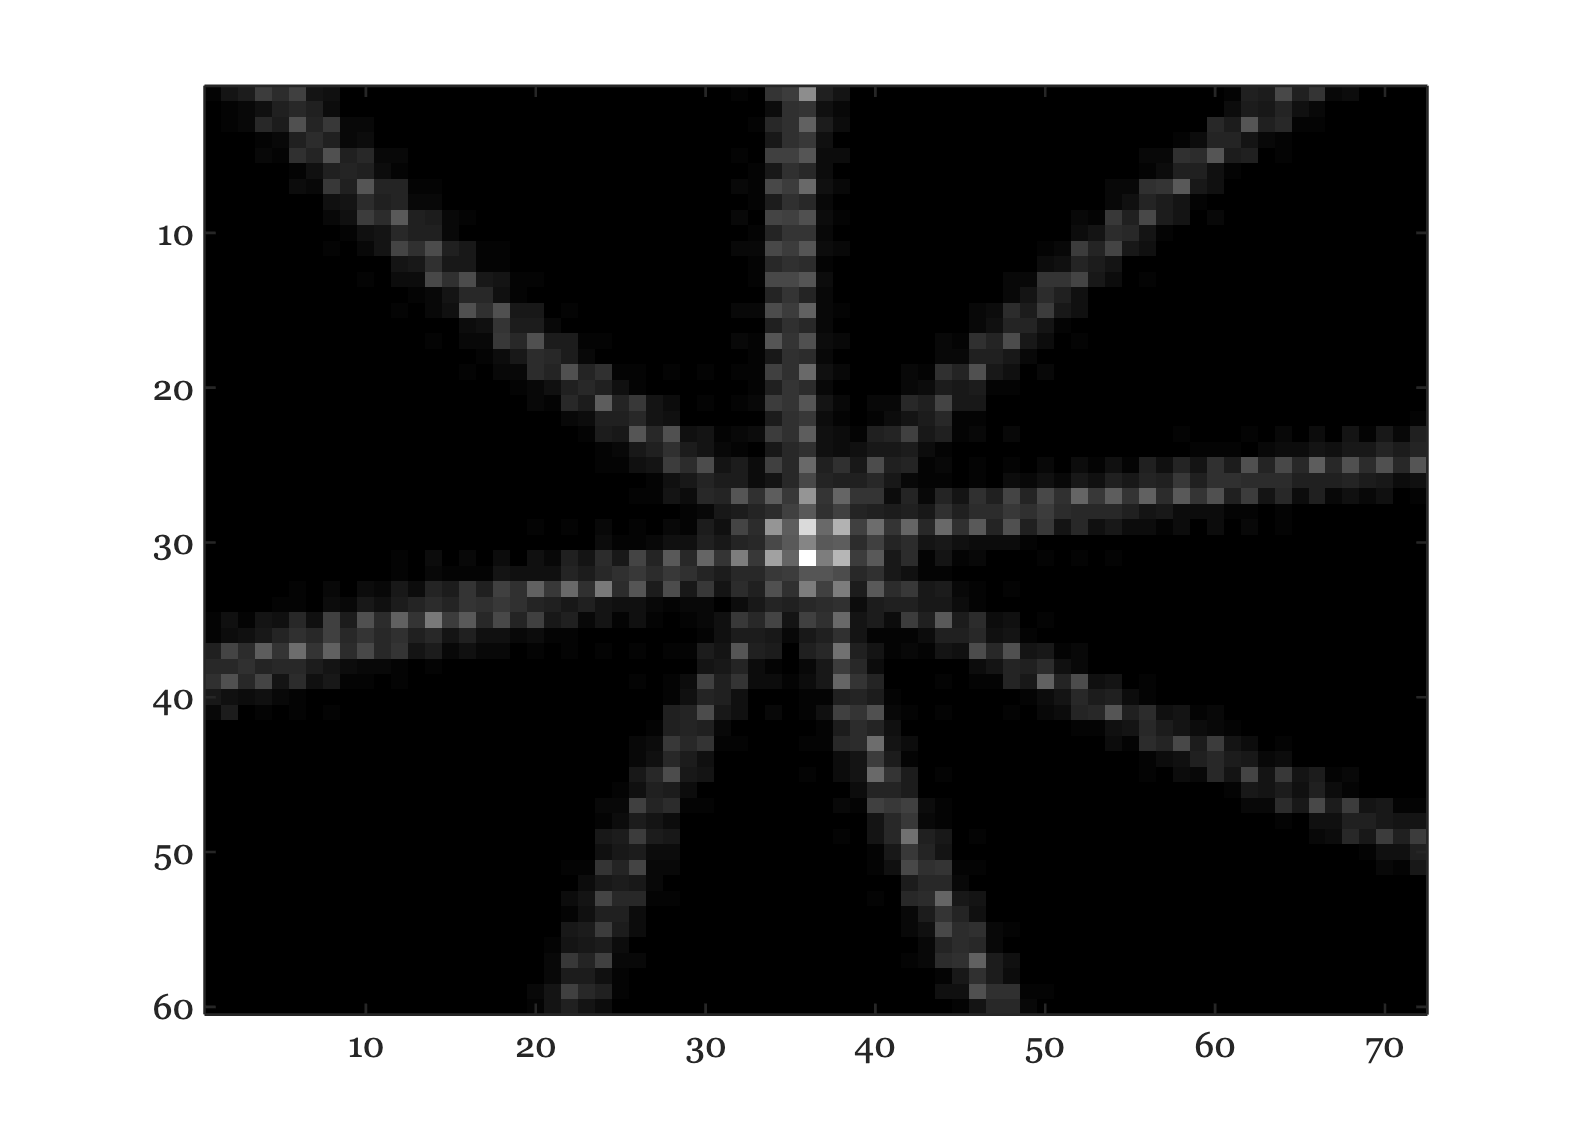

% This is the final, summed voltages for each row.
final = zeros(sz);

% Each row is read out for some proportion of the capture.
% This is the list of sensor rows that are read out from each image.
% we will add these in to the final image.
slist = 1:round(expTime/perRow);
z = zeros(nFrames,1);
z(slist) = 1;

% Sum across a sliding temporal range
ieFigure; colormap(gray(64)); axis image; axis off
fps = 7;
for rr = 1:sz(1)
    slist = slist+1;
    z = zeros(nFrames,1);
    z(slist) = 1;
    tmp = squeeze(v(rr,:,:));
    final(rr,:) = tmp*z;
    imagesc(final); pause(1/fps);
end

## Image process and then show the final color image

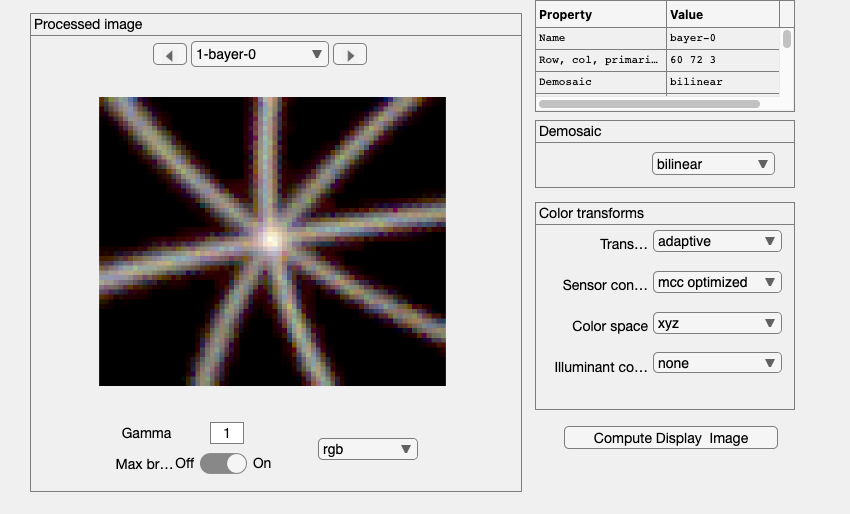

srs = sensorSet(sensor,'volts',final);
ip = ipCreate;

ip = ipCompute(ip,srs);
ipWindow(ip);